# Hoseini et al. (2015) - Adaptive Staircase Measurement of Hand Proprioception

Created June 5, 2021.

clear; clc; 
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Hoseini_15')

## Initial Conditions

% ICs
finger_length = 4; % cm 
xy_end = @(radius, deg, originX, originY) [radius * cosd(deg) + originX, radius * sind(deg) + originY]; % finger end position 
Roffset = 90; % 90 deg offset for right hand 
finger_deg = 55 + Roffset; % finger degree
trial = 1; % trial number 
terminate_reversals = 4; % terminate algorithm after this number of reversals 
logistic = @(heat, midpoint, xdata) 1 ./ (1 + exp(-heat * (xdata - midpoint))); % logistic function 
observer_bias = 3.4; % deg 
observer_sensitivity = findSigma(observer_bias, 6.3, logistic, [-30, 30]); % deg 

Sensitivty = 6.67e+00

line_LR_finger = 1; % line left or right of finger (1 = right, 0, = left)
% empty arrays to record angles and responses in 
anglesAll = []; 
responsesAll = []; 
staircaseIdx = []; 
count = 1;
filename = 'sim4.gif'; 

## Staircase 1 & 2 

% ICs
num_staircases = 2; 

for staircase = 1:num_staircases
    % set / reset
    num_reversals = 0; 
    if rem(staircase,2) ~= 0 
        offset = 30;
    elseif rem(staircase,2) == 0
        offset = -30; 
    end
    line_deg = finger_deg + offset; 
    step_size = 10; % intial step size 
    clearvars response_n1
    % run 
    while num_reversals ~= terminate_reversals
        % record current angle 
        anglesAll = [anglesAll, line_deg];
        
         % response 
        observer_response = logistic(observer_sensitivity, observer_bias, finger_deg+observer_bias*2 - line_deg);
        
        if observer_response >= 0.9
            response = randsample([0 1], 1, true, [1 0]);
            
        elseif observer_response >= 0.75 && observer_response < 0.9
            response = randsample([0 1], 1, true, [0.9 0.1]);
            
        elseif observer_response >= 0.55 && observer_response < 0.75
            response = randsample([0 1], 1, true, [0.8 0.2]);
            
        elseif observer_response >= 0.45 && observer_response < 0.55
            response = randsample([0 1], 1, true, [0.5 0.5]);
            
        elseif observer_response >= 0.25 && observer_response < 0.45
            response = randsample([0 1], 1, true, [0.2 0.8]);
            
        elseif observer_response > 0.01 && observer_response < 0.25
            response = randsample([0 1], 1, true, [0.1 0.9]);
            
        elseif observer_response <= 0.1
            response = randsample([0 1], 1, true, [0 1]);
            
        end
        
        % record response 
        responsesAll = [responsesAll, response]; 
        
        % choose next stimulus 
        if response == 1 % right 
            line_deg = line_deg - step_size; 
        elseif response == 0 % left 
            line_deg = line_deg + step_size; 
        end
        
        % which staircase on 
        staircaseIdx(count) = staircase; 
        count = count+1; 
        
        % update 
        if exist("response_n1", 'var') && response_n1 ~= response 
            step_size = step_size / 2; 
            num_reversals = num_reversals+1; 
            if response == 1
                response_n1 = 0; 
            elseif response == 0
                response_n1 = 1;
            end
            continue
        end
        response_n1 = response; 
        
    end
end

## New measurements 

angles1 = anglesAll(staircaseIdx == 1); angles2 = anglesAll(staircaseIdx == 2);
last8angles = [angles1(end-3:end), angles2(end-3:end)];
staircase_center_sensitivity = range(last8angles) * 0.75; 
staircase_center_bias = mean(last8angles);

## Fit data 1

% unique 
anglesUn = unique(anglesAll); 
if length(anglesUn) == length(anglesAll)
    probUn = responsesAll; 
else
    probUn = nan([1 length(anglesUn)]);
    for i = 1:length(anglesUn)
        logIdx = anglesUn(i) == anglesAll; 
        probUn(i) = mean(responsesAll(logIdx)); 
    end
end
coeffs = mle(probUn, 'distribtion', 'logistic')

coeffs =     0.3590    0.4178


% coeffs = lsqcurvefit(@(x, xdata) 1 ./ (1 + exp(-x(1) * (xdata - x(2)))), [0 0], anglesUn-(90+55), probUn)
observer_sensitivity_1 = coeffs(1); 
observer_bias_1 = coeffs(2); 

## Staircase 3 - 6

% ICs
num_staircases = 4; 

for staircase = 3:3+num_staircases
    % set / reset
    num_reversals = 0; 
    if rem(staircase,2) ~= 0 
        offset = staircase_center_sensitivity;
    elseif rem(staircase,2) == 0
        offset = -staircase_center_sensitivity; 
    end
    line_deg = staircase_center_bias + offset; 
    step_size = 5; % intial step size (deg)
    clearvars response_n1
    % run 
    while num_reversals ~= terminate_reversals
        % record current angle 
        anglesAll = [anglesAll, line_deg];
        
         % response 
        observer_response = logistic(observer_sensitivity, observer_bias, finger_deg+observer_bias*2 - line_deg);
        
        if observer_response >= 0.9
            response = randsample([0 1], 1, true, [1 0]);
            
        elseif observer_response >= 0.75 && observer_response < 0.9
            response = randsample([0 1], 1, true, [0.9 0.1]);
            
        elseif observer_response >= 0.55 && observer_response < 0.75
            response = randsample([0 1], 1, true, [0.8 0.2]);
            
        elseif observer_response >= 0.45 && observer_response < 0.55
            response = randsample([0 1], 1, true, [0.5 0.5]);
            
        elseif observer_response >= 0.25 && observer_response < 0.45
            response = randsample([0 1], 1, true, [0.2 0.8]);
            
        elseif observer_response > 0.01 && observer_response < 0.25
            response = randsample([0 1], 1, true, [0.1 0.9]);
            
        elseif observer_response <= 0.1
            response = randsample([0 1], 1, true, [0 1]);
            
        end
        
        % record response 
        responsesAll = [responsesAll, response]; 
        
        % choose next stimulus 
        if response == 1 % right 
            line_deg = line_deg - step_size; 
        elseif response == 0 % left 
            line_deg = line_deg + step_size; 
        end
        
        % which staircase on 
        staircaseIdx(count) = staircase; 
        count = count+1; 
        
        % update 
        if exist("response_n1", 'var') && response_n1 ~= response 
            step_size = step_size / 2; 
            num_reversals = num_reversals+1; 
            if response == 1
                response_n1 = 0; 
            elseif response == 0
                response_n1 = 1;
            end
            continue
        end
        response_n1 = response; 
        
    end
end

## Fit data 2

% unique 
anglesUn = unique(anglesAll); 
if length(anglesUn) == length(anglesAll)
    probUn = responsesAll; 
else
    probUn = nan([1 length(anglesUn)]);
    for i = 1:length(anglesUn)
        logIdx = anglesUn(i) == anglesAll; 
        probUn(i) = mean(responsesAll(logIdx)); 
    end
end
coeffs = mle(probUn, 'distribtion', 'logistic')

coeffs =     0.5101    0.4256


% coeffs = lsqcurvefit(@(x, xdata) 1 ./ (1 + exp(-x(1) * (xdata - x(2)))), [0.1 0], anglesUn-(90+55), probUn)
observer_sensitivity_2 = coeffs(1); 
observer_bias_2 = coeffs(2); 

## Visualize

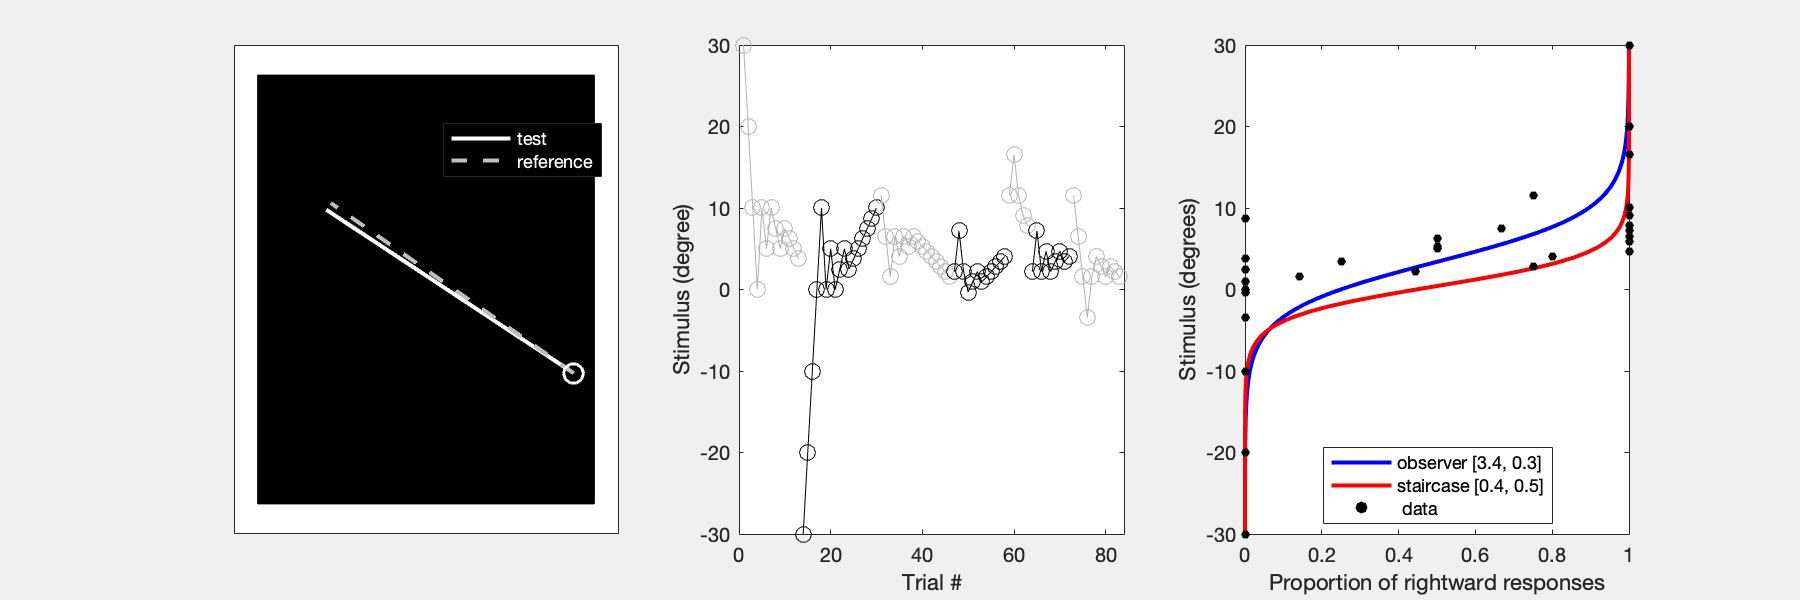

figure('visible', 'on', 'position', [500 500 900 300]);

subplot(1,3,1); % finger 
line_end = xy_end(finger_length, anglesAll(1), 0, 0); 
finger_end = xy_end(finger_length, finger_deg, 0, 0);
plot([0 line_end(1)], [0 line_end(2)], 'w-', 'linewidth', 2, 'displayname', 'test'); % test line 
hold on 
plot([0 finger_end(1)], [0 finger_end(2)], '--', 'linewidth', 2, 'color', [.75 .75 .75], 'displayname', 'reference'); % true finger 
% axis([-7 7 -1 4])
axis equal 
axis padded 
kBackground(gca); 
plot(0,0, 'wo', 'markersize', 10, 'linewidth', 1.5, 'HandleVisibility','off'); % MCP joint 
xticks([]); yticks([]);
% xlabel('a.u.'); ylabel('a.u.')
legend('location', 'best', "Color",'k', "TextColor",'w')
ax1 = gca(); 

subplot(1,3,2); % experiment 
plot(1, anglesAll(1)-finger_deg, '-o', 'markersize', 8, 'color', [.7 .7 .7]);
hold on 
ylim([-30 30]); 
xlabel('Trial #'); ylabel('Stimulus (degree)')
% legend('location', 'best')
ax2 = gca();

subplot(1,3,3); % PF 
xdata = linspace(ax2.YLim(1), ax2.YLim(2)); 
plot(logistic(observer_sensitivity, observer_bias, xdata), xdata,  'b-', 'linewidth', 2, 'displayname', sprintf('observer [%.1f, %.1f]', observer_bias, observer_sensitivity)); 
hold on 
plot(nan, nan, 'r-', 'linewidth', 2, 'displayname', 'staircase')
legend('location', 'best')
xlim([0 1]); ylim(ax2.YLim);
ylabel('Stimulus (degrees)'); xlabel('Proportion of rightward responses')
ax3 = gca(); 

writeGif(filename, 1, 0.5); 

for t = 2:length(anglesAll)
    
    % subplot(1,3,1)
    line_end = xy_end(finger_length, anglesAll(t), 0, 0); 
    set(ax1.Children(2), 'xdata', [0 line_end(1)]);
    set(ax1.Children(2), 'ydata', [0 line_end(2)]); 
    
    % subplot(1,3,2)
    if staircaseIdx(t) - staircaseIdx(t-1) ~= 0 
        subplot(1,3,2)
        if rem(staircaseIdx(t),2) == 0 
            plot(t, anglesAll(t)-finger_deg, 'k-o', 'markersize', 8);
        else
            plot(t, anglesAll(t)-finger_deg, '-o', 'markersize', 8, 'color', [.7 .7 .7]);
        end
    end
    set(ax2.Children(1), 'xdata', [ax2.Children(1).XData, t]);
    set(ax2.Children(1), 'ydata', [ax2.Children(1).YData, anglesAll(t)-finger_deg]);
    set(ax2, 'xlim', [0 t+1])
    
    % subplot(1,3,3)
    % unique 
    anglesUn = unique(anglesAll(1:t)); 
    if length(anglesUn) == length(anglesAll(1:t))
        probUn = responsesAll(1:t); 
    else
        probUn = nan([1 length(anglesUn)]);
        for i = 1:length(anglesUn)
            logIdx = anglesUn(i) == anglesAll(1:t); 
            probUn(i) = mean(responsesAll(logIdx)); 
        end
    end
    subplot(1,3,3)
    if t>2
        delete(ax3.Children(1))
    end
    scatter(probUn, anglesUn-finger_deg, 20, 'filled', 'k', 'displayname',' data')
    if staircaseIdx(t) == 2 && staircaseIdx(t+1) == 3
        set(ax3.Children(2), 'ydata', xdata)
        set(ax3.Children(2), 'xdata', logistic(observer_sensitivity_1, observer_bias_1, xdata)); 
        set(ax3.Children(2), 'displayname', sprintf('staircase [%.1f, %.1f]', observer_bias_1, observer_sensitivity_1));
    elseif t == length(anglesAll)
        set(ax3.Children(2), 'xdata', logistic(observer_sensitivity_2, observer_bias_2, xdata));
        set(ax3.Children(2), 'displayname', sprintf('staircase [%.1f, %.1f]', observer_bias_2, observer_sensitivity_2));
    end
    
    writeGif(filename, t, 0.5); 
%     pause(0.1)
end